clear

syms g v gamma
a_n = g*cos(gamma);
rho = dot(v, v)/a_n

$$rho = \frac{v\,\bar{v}}{g\,\cos\left(\gamma \right)}$$


gamma_dot = -v/rho

$$gamma\_dot = -\frac{g\,\cos\left(\gamma \right)}{\bar{v}}$$

g = 9.8065;
v = 500; % m/s
t_span = [0, 100];

gamma_dot = subs(gamma_dot)

$$gamma\_dot = -\frac{19613\,\cos\left(\gamma \right)}{1000000}$$

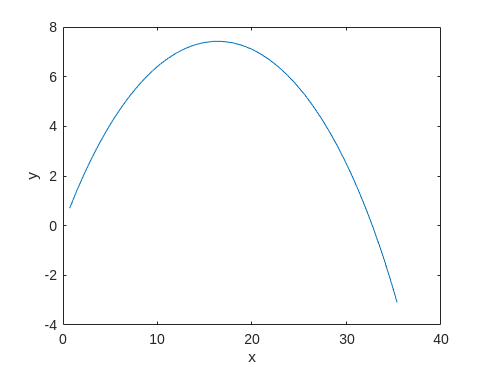

[~, gamma] = ode45(@(t, gama) double(subs(gamma_dot,gamma,gama)), t_span, 45*pi/180);

plot(cumsum(cos(gamma)), cumsum(sin(gamma)));
xlabel('x'); ylabel('y');